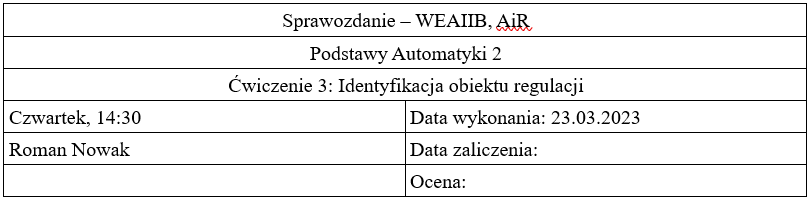

**Cel ćwiczenia**

Celem ćwiczenia jest zapoznanie się z przykładami identyfikacji parametrów modelu zastępczego rzeczywistego obiektu regulacji. Obiekt rzeczywisty jest doświadczalnym obiektem cieplnym (system dynamiczny nieskończenie wymiarowy)

Zadanie polega na wyznaczeniu przybliżonej transmitancji rzeczywistego obiektu, którego odpowiedzi skokowe wyznczono doświadczalnie, za pomocą poniższych modeli:

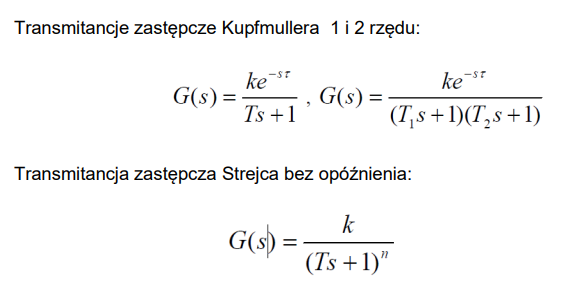

load pomiary_3out.mat;

Error using load
'pomiary_3out.mat' is not found in the current folder or on the MATLAB path, but exists in:
    D:\programowanie\Matlab\PA2

Change the MATLAB current folder or add its folder to the MATLAB path.


t = 1:300;

figure; plot(t, pomiary_3out);

y1=pomiary_3out(:,1) - pomiary_3out(1,1);
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
y3=pomiary_3out(:,3) - pomiary_3out(1,3);

plot(t, y1);
plot(t, y2);
plot(t, y3);

% Wzmocnienia statyczne
k1=y1((300)-y1(1))/1.0
k2=y2((300)-y2(1))/1.0
k3=y3((300)-y3(1))/1.0


Transmitancja zastępcza pierwszego obiektu za pomocą obiektu inercyjnego pierwszego rzędu z opóźnieniem.

figure; hold on;
plot(t, y1, 'b', t, k1 .* ones(length(t)), '--')
% [x1, x2] = ginput(2)
x1 = [9.6685; 45.0276];
x2 = [0; 0.7179];
plot(x1, x2, '--') % x1 i x2 uzyskane za pomocą funkcji ginput
grid on

teta = round(x1(1), 1) % przybliżona wartość opóźnienia odczytana z wykresu
T = round(x1(2) - x1(1), 1) % przybliżona wartość stałej czasowej odczytana z wykresu

licz = [0 k1];
mian = [T 1];
obiekt = tf(licz, mian);
set(obiekt,'outputdelay', teta);
[ym1, tm] = step(obiekt, t);
plot(tm, ym1)
hold off;

MSE = sum((y1-ym1).^2)
u = ones(size(y1));
y1exper = iddata(y1, u, 1);
[~, fit, ~] = compare(y1exper, obiekt, 300)


Transmitancja zastępcza pierwszego obiektu za pomocą obiektu inercyjnego drugiego rzędu z opóźnieniem.

T1 = 28, T2 = 4, teta = 5.5 % Wartości dobrane na podst. wykresu
licz = [0 0 k1]; mian = [T1 * T2, T1 + T2, 1];
obiekt = tf(licz, mian);
set(obiekt, 'outputdelay', teta)

[ym1, ~] = step(obiekt, t);
u = ones(size(y1));
y1exper = iddata(y1, u, 1);
figure;
compare(y1exper, obiekt, 300);
MSE = sum((y1-ym1).^2)


Transmitancja zastępcza pierwszego obiektu za pomocą obiektu inercyjnego n-tego rzędu rzędu

n = 2;
T = 19;

licz = [0, k1^(1/n)];
mian = [T, 1];

licz_n = licz;
mian_n = mian;

for i = (1:n-1)
    [licz_n, mian_n] = series(licz_n, mian_n, licz, mian);
end

obiekt = tf(licz_n,mian_n);
[ym1, ~] = step(obiekt, t);
u = ones(size(y1));
y1exper = iddata(y1, u, 1);
figure;
compare(y1exper, obiekt, 300);
MSE = sum((y1-ym1).^2)


Transmitancja zastępcza drugiego obiektu za pomocą obiektu inercyjnego pierwszego rzędu z opóźnieniem.

figure; hold on;
plot(t, y2, 'b', t, k2 .* ones(length(t)), '--')
%[x1, x2] = ginput(2)
x1 = [23.4807; 69.8895];
x2 = [0; 0.2576];
plot(x1, x2, '--') % x1 i x2 uzyskane za pomocą funkcji ginput
grid on

teta = round(x1(1), 1) % przybliżona wartość opóźnienia odczytana z wykresu
T = round(x1(2) - x1(1), 1) % przybliżona wartość stałej czasowej odczytana z wykresu

licz = [0 k2];
mian = [T 1];
obiekt = tf(licz, mian);
set(obiekt,'outputdelay', teta);
[ym2, tm] = step(obiekt, t);
plot(tm, ym2)
hold off;

MSE= sum((y2-ym2).^2)
u = ones(size(y2));
y2exper = iddata(y2, u, 1);
[~, fit, ~] = compare(y2exper, obiekt, 300)

Transmitancja zastępcza drugiego obiektu za pomocą obiektu inercyjnego drugiego rzędu z opóźnieniem.

T1 = 36, T2 = 12, teta = 15 % Wartości dobrane na podst. wykresu
licz = [0 0 k2]; mian = [T1 * T2, T1 + T2, 1];
obiekt = tf(licz, mian);
set(obiekt, 'outputdelay', teta)

[ym2, ~] = step(obiekt, t);
u = ones(size(y2));
y2exper = iddata(y2, u, 1);
figure;
compare(y2exper, obiekt, 300);
MSE = sum((y2-ym2).^2)


Transmitancja zastępcza drugiego obiektu za pomocą obiektu inercyjnego n-tego rzędu rzędu

n = 3;
T = 21;

licz = [0, k2^(1/n)];
mian = [T, 1];

licz_n = licz;
mian_n = mian;

for i = (1:n-1)
    [licz_n, mian_n] = series(licz_n, mian_n, licz, mian);
end


obiekt = tf(licz_n,mian_n);
[ym2, ~] = step(obiekt, t);
u = ones(size(y2));
y2exper = iddata(y2, u, 1);
figure;
compare(y2exper, obiekt, 300);
MSE = sum((y2-ym2).^2)


Transmitancja zastępcza trzeciego obiektu za pomocą obiektu inercyjnego pierwszego rzędu z opóźnieniem.

figure; hold on;
plot(t, y3, 'b', t, k3 .* ones(length(t)), '--')
% [x1, x2] = ginput(2)
x1 = [42.2652; 102.4862];
x2 = [0; 0.0737];
plot(x1, x2, '--') % x1 i x2 uzyskane za pomocą funkcji ginput
grid on

teta = round(x1(1), 1) % przybliżona wartość opóźnienia odczytana z wykresu
T = round(x1(2) - x1(1), 1) % przybliżona wartość stałej czasowej odczytana z wykresu

licz = [0 k3];
mian = [T 1];
obiekt = tf(licz, mian);
set(obiekt,'outputdelay', teta);
[ym3, tm] = step(obiekt, t);
plot(tm, ym3)
hold off;

MSE= sum((y3-ym3).^2)
u = ones(size(y3));
y3exper = iddata(y3, u, 1);
[~, fit, ~] = compare(y3exper, obiekt, 300)

Transmitancja zastępcza trzeciego obiektu za pomocą obiektu inercyjnego drugiego rzędu z opóźnieniem.

T1 = 42, T2 = 38, teta = 26 % Wartości dobrane na podst. wykresu
licz = [0 0 k3]; mian = [T1 * T2, T1 + T2, 1];
obiekt = tf(licz, mian);
set(obiekt, 'outputdelay', teta)

[ym3, ~] = step(obiekt, t);
u = ones(size(y3));
y3exper = iddata(y3, u, 1);
figure;
compare(y3exper, obiekt, 300);
MSE = sum((y3-ym3).^2)


Transmitancja zastępcza trzeciego obiektu za pomocą obiektu inercyjnego n-tego rzędu rzędu

n = 3;
T = 34;

licz = [0, k3^(1/n)];
mian = [T, 1];

licz_n = licz;
mian_n = mian;

for i = (1:n-1)
    [licz_n, mian_n] = series(licz_n, mian_n, licz, mian);
end

obiekt = tf(licz_n,mian_n);
[ym3, ~] = step(obiekt, t);
u = ones(size(y3));
y3exper = iddata(y3, u, 1);
figure;
compare(y3exper, obiekt, 300);
MSE = sum((y3-ym3).^2)

**Wnioski**

Tabela porównująca otrzymane wyniki

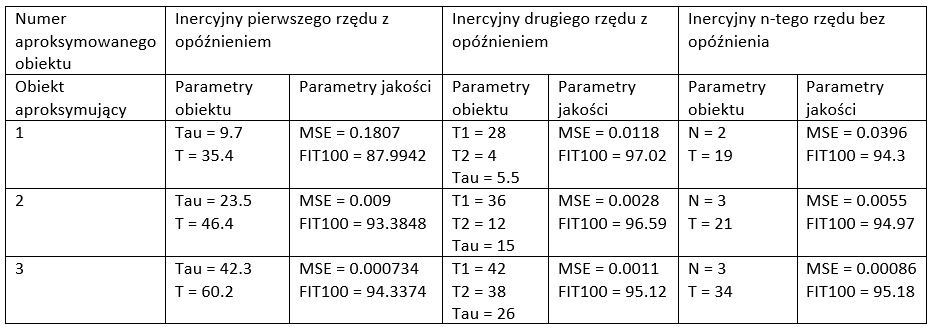

W przypadku dwóch pierwszych obiektów, najdokładniejsze odpowiedzi skokowe udało się uzuskać, przybliżając je obiektem inercyjnym II rzędu z opóźnieniem, a najgorzej sprawdził się obiekt inercyjny I rzędu. Dla trzeciego obiektu, każda z aproksymacji była porównywalnie dobra, najlepsze wartości parametrów MSE i FIT100, uzyskałem przy zastosowaniu obiektu n-tego rzędu.

Najlepsza, ze względu na paramter MSE aproksymacja wystąpiła w obiekcie 3, dla obiektu inercyjnego I rzędu z opóźnieniem

Najlepsza, ze względu na paramter FIT100 aproksymacja wystąpiła w obiekcie 1, dla obiektu inercyjnego II rzędu z opóźnieniem